clear;
clc;

%input
x_position=-2:0.2:2 %%shifted to right side

x_position =    -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


y_position=-2:0.2:2

y_position =    -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


theta_r_increment = 5

theta_r_increment = 5

theta_r_in=0:theta_r_increment:180

theta_r_in =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180



%input index
x_index = 1:1:length(x_position)

x_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


y_index = 1:1:length(y_position)

y_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


theta_r_index = 1:1:length(theta_r_in)

theta_r_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37



%theta position
theta_position=0

theta_position = 0


Num_turns=1;
Num_series=1;
Num_parallel=1;

close all

for y=y_index
for x=x_index
for r=theta_r_index    

openfemm;
newdocument(0);
path='C:/femm42/';
name_fem='ebike.fem';

mi_saveas([path,name_fem]);
Hc=900000;

u_r_mag=1.05;
mi_getmaterial('Air')
mi_getmaterial('M-19')
mi_addmaterial('NdFeB',u_r_mag,u_r_mag,Hc,0,0.556);

mi_addboundprop('A_0',0,0,0,0)

%%% hall, magnet position
depth = 24.5;
pole_number= 4;
airgap = 0.5;
m_thickness=1.7;
m_width=9.3;
m_in=m_thickness;
D_rotor_outer=26;
D_rotor_inner = 18;% m location
D_shaft=8;
R_sue_3=D_rotor_outer*0.5+airgap;
D_stator_outer =  100;

mi_probdef(0,'millimeters','planar',1e-008,depth,30);

sensor_r=15;

x1=0;
y1=0;
k=D_stator_outer*0.5;
mi_addnode(x1+k,y1);
mi_addnode(x1-k,y1);
mi_addarc(x1+k,y1,x1-k,y1,180,5);
mi_addarc(x1-k,y1,x1+k,y1,180,5);


mi_clearselected();
mi_selectarcsegment(0,k);
mi_setarcsegmentprop(1,'A_0', 0,0);
mi_selectarcsegment(0,-k) ;
mi_setarcsegmentprop(1,'A_0', 0,0);


x1=0;
y1=0;
k=D_shaft*0.5;
mi_addnode(x1+k,y1);
mi_addnode(x1-k,y1);
mi_addarc(x1+k,y1,x1-k,y1,180,5);
mi_addarc(x1-k,y1,x1+k,y1,180,5);
A_coil_height=6;
zz=1;


mi_clearselected();
mi_addblocklabel(0,0);
mi_selectlabel(0,0);
mi_setblockprop('Air',1, 0, '<None>', 0, 0, 0);

mi_zoomnatural();
mi_clearselected()
mi_refreshview()

x1=0;
y1=0;
k=D_rotor_inner/2+m_thickness;
mi_addnode(x1+k,y1);
mi_addnode(x1-k,y1);
mi_addarc(x1+k,y1,x1-k,y1,180,5);
mi_addarc(x1-k,y1,x1+k,y1,180,5);

x1=0;
y1=0;
k=D_rotor_inner/2;
mi_addnode(x1+k,y1);
mi_addnode(x1-k,y1);
mi_addarc(x1+k,y1,x1-k,y1,180,5);
mi_addarc(x1-k,y1,x1+k,y1,180,5);

mi_addsegment(D_rotor_inner/2,0,D_rotor_inner/2+m_thickness,0)
mi_addsegment(-D_rotor_inner/2,0,-D_rotor_inner/2-m_thickness,0)

mi_addnode(0, D_rotor_inner/2+m_thickness);
mi_addnode(0, -D_rotor_inner/2-m_thickness);
mi_addnode(0, D_rotor_inner/2);
mi_addnode(0, -D_rotor_inner/2);
mi_addsegment(0,D_rotor_inner/2,0,D_rotor_inner/2+m_thickness)
mi_addsegment(0,-D_rotor_inner/2,0,-D_rotor_inner/2-m_thickness)



mi_selectcircle(0,0,(D_rotor_outer+airgap)*0.5,4);
mi_copyrotate2(0,0,360/2,2,4);
mi_addsegment((D_rotor_inner/2)-m_in+m_thickness,m_width/2,(D_rotor_inner/2)-m_in+m_thickness,-m_width/2)
mi_addsegment(-((D_rotor_inner/2)-m_in+m_thickness),m_width/2,-((D_rotor_inner/2)-m_in+m_thickness),-m_width/2)


z=1;
mi_clearselected();
mi_addblocklabel(cos((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_selectlabel(cos((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_setblockprop('NdFeB',1,0,'None',90+180/pole_number+(z-1)*4*180/pole_number,(10+z*2-1),1);
z=2;
mi_clearselected();
mi_addblocklabel(cos((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_selectlabel(cos((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_setblockprop('NdFeB',1,0,'None',90+180/pole_number+(z-1)*4*180/pole_number,(10+z*2-1),1);

z=1;
mi_clearselected();
mi_addblocklabel(cos((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_selectlabel(cos((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_setblockprop('NdFeB',1,0,'None',180/pole_number+(z-1)*4*180/pole_number,(10+z*2-1),1);
z=2;
mi_clearselected();
mi_addblocklabel(cos((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_selectlabel(cos((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5,sin((pi/2+pi/2+pi/pole_number+(z-1)*4*pi/pole_number))*(D_rotor_inner+m_thickness)*0.5);
mi_setblockprop('NdFeB',1,0,'None',180/pole_number+(z-1)*4*180/pole_number,(10+z*2-1),1);


mi_clearselected();
mi_addblocklabel(0,0);
mi_selectlabel(0,0);
mi_setblockprop('Air',1, 0, '<None>', 0, 10, 0);

mi_clearselected();
mi_addblocklabel(0,D_shaft*0.5+1);
mi_selectlabel(0,D_shaft*0.5+1);
mi_setblockprop('M-19',1, 0, '<None>', 0, 10, 0);

mi_clearselected();
mi_addblocklabel(0,R_sue_3-0.1);
mi_selectlabel(0,R_sue_3-0.1);
mi_setblockprop('Air',1, 0, '<None>', 0, 0, 0);


mi_selectcircle(0,0,(D_rotor_outer*0.5+airgap*0.5),4)
mi_seteditmode('group')
mi_moverotate(0,0,theta_position+90)

mi_selectcircle(0,0,(D_stator_outer*0.5+airgap*0.5),4)
mi_seteditmode('group')
mi_moverotate(0,0,-90)


%% 

%%%%%%%%%%%%% Post analysis


% time.FEA_run=round(toc)

mi_selectcircle(0,0,(D_rotor_outer*0.5+airgap*0.5),4)
mi_seteditmode('group')
mi_moverotate(0,0,45)

    
mi_selectcircle(0,0,(D_rotor_outer*0.5+airgap*0.5),4)
mi_seteditmode('group')
mi_moverotate(0,0,theta_r_in(1,r))
mi_selectcircle(0,0,(D_rotor_outer*0.5+airgap*0.5),4)
mi_seteditmode('group')
mi_movetranslate(x_position(1,x),y_position(1,y))

%%analyzing
mi_analyze(1)
mi_loadsolution()

% temap_theta_r=temap_theta_r+10;

xpoint0=sensor_r*cos(0*pi/180); ypoint0=sensor_r*sin(0*pi/180);
xpoint15=sensor_r*cos((15)*pi/180); ypoint15=sensor_r*sin((15)*pi/180);
xpoint30=sensor_r*cos((30)*pi/180); ypoint30=sensor_r*sin((30)*pi/180);
xpoint45=sensor_r*cos((45)*pi/180); ypoint45=sensor_r*sin((45)*pi/180);
xpoint60=sensor_r*cos((60)*pi/180); ypoint60=sensor_r*sin((60)*pi/180);
xpoint75=sensor_r*cos((75)*pi/180); ypoint75=sensor_r*sin((75)*pi/180);
xpoint90=sensor_r*cos((90)*pi/180); ypoint90=sensor_r*sin((90)*pi/180);
xpoint105=sensor_r*cos((105)*pi/180); ypoint105=sensor_r*sin((105)*pi/180);
xpoint120=sensor_r*cos((120)*pi/180); ypoint120=sensor_r*sin((120)*pi/180);
xpoint135=sensor_r*cos((135)*pi/180); ypoint135=sensor_r*sin((135)*pi/180);
xpoint150=sensor_r*cos((150)*pi/180); ypoint150=sensor_r*sin((150)*pi/180);
xpoint165=sensor_r*cos((165)*pi/180); ypoint165=sensor_r*sin((165)*pi/180);
xpoint180=sensor_r*cos((180)*pi/180); ypoint180=sensor_r*sin((180)*pi/180);
xpoint195=sensor_r*cos((195)*pi/180); ypoint195=sensor_r*sin((195)*pi/180);
xpoint210=sensor_r*cos((210)*pi/180); ypoint210=sensor_r*sin((210)*pi/180);
xpoint225=sensor_r*cos((225)*pi/180); ypoint225=sensor_r*sin((225)*pi/180);
xpoint240=sensor_r*cos((240)*pi/180); ypoint240=sensor_r*sin((240)*pi/180);
xpoint255=sensor_r*cos((255)*pi/180); ypoint255=sensor_r*sin((255)*pi/180);
xpoint270=sensor_r*cos((270)*pi/180); ypoint270=sensor_r*sin((270)*pi/180);
xpoint285=sensor_r*cos((285)*pi/180); ypoint285=sensor_r*sin((285)*pi/180);
xpoint300=sensor_r*cos((300)*pi/180); ypoint300=sensor_r*sin((300)*pi/180);
xpoint315=sensor_r*cos((315)*pi/180); ypoint315=sensor_r*sin((315)*pi/180);
xpoint330=sensor_r*cos((330)*pi/180); ypoint330=sensor_r*sin((330)*pi/180);
xpoint345=sensor_r*cos((345)*pi/180); ypoint345=sensor_r*sin((345)*pi/180);

%%% get the values associated with the point at x,y RETURN values in order

pv0 = mo_getpointvalues(xpoint0,ypoint0);
pv15 = mo_getpointvalues(xpoint15,ypoint15);
pv45 = mo_getpointvalues(xpoint45,ypoint45);
pv30 = mo_getpointvalues(xpoint30,ypoint30);
pv60 = mo_getpointvalues(xpoint60,ypoint60);
pv75 = mo_getpointvalues(xpoint75,ypoint75);
pv90 = mo_getpointvalues(xpoint90,ypoint90);
pv105 = mo_getpointvalues(xpoint105,ypoint105);
pv120 = mo_getpointvalues(xpoint120,ypoint120);
pv135 = mo_getpointvalues(xpoint135,ypoint135);
pv150 = mo_getpointvalues(xpoint150,ypoint150);
pv165 = mo_getpointvalues(xpoint165,ypoint165);
pv180 = mo_getpointvalues(xpoint180,ypoint180);
pv195 = mo_getpointvalues(xpoint195,ypoint195);
pv210 = mo_getpointvalues(xpoint210,ypoint210);
pv225 = mo_getpointvalues(xpoint225,ypoint225);
pv240 = mo_getpointvalues(xpoint240,ypoint240);
pv255 = mo_getpointvalues(xpoint255,ypoint255);
pv270 = mo_getpointvalues(xpoint270,ypoint270);
pv285 = mo_getpointvalues(xpoint285,ypoint285);
pv300 = mo_getpointvalues(xpoint300,ypoint300);
pv315 = mo_getpointvalues(xpoint315,ypoint315);
pv330 = mo_getpointvalues(xpoint330,ypoint330);
pv345 = mo_getpointvalues(xpoint345,ypoint345);

%%% getting flux density of x, y
B_0x(r,x,y)=pv0(2);B_0y(r,x,y)=pv0(3); 
% B_0abs(theta_r,x,y)= (B_0x(theta_r,x,y)^2+B_0y(theta_r,x,y)^2)^0.5;
temp = (B_0x(r,x,y) + j * B_0y(r,x,y)) .* exp(-j*(0)*pi/180);
B_0abs(r,x,y) = real(temp);

% B_15x(r,x,y)=pv15(2); B_15y(r,x,y)=pv15(3);
% % B_0abs(theta_r,x,y)= (B_0x(theta_r,x,y)^2+B_0y(theta_r,x,y)^2)^0.5;
% temp = (B_15x(r,x,y) + j * B_15y(r,x,y)) .* exp(-j*(15)*pi/180);
% B_15abs(r,x,y) = real(temp);

B_30x(r,x,y)=pv30(2); B_30y(r,x,y)=pv30(3);
% B_0abs(theta_r,x,y)= (B_0x(theta_r,x,y)^2+B_0y(theta_r,x,y)^2)^0.5;
temp = (B_30x(r,x,y) + j * B_30y(r,x,y)) .* exp(-j*(30)*pi/180);
B_30abs(r,x,y) = real(temp);

% B_45x(r,x,y)=pv45(2); B_45y(r,x,y)=pv45(3);
% % B_0abs(theta_r,x,y)= (B_0x(theta_r,x,y)^2+B_0y(theta_r,x,y)^2)^0.5;
% temp = (B_45x(r,x,y) + j * B_45y(r,x,y)) .* exp(-j*(45)*pi/180);
% B_45abs(r,x,y) = real(temp);

B_60x(r,x,y)=pv60(2); B_60y(r,x,y)=pv60(3); 
% B_60abs(theta_r,x,y)= (B_60x(theta_r,x,y)^2+B_60y(theta_r,x,y)^2)^0.5;
temp = (B_60x(r,x,y) + j * B_60y(r,x,y)) .* exp(-j*(60)*pi/180);
B_60abs(r,x,y) = real(temp);

% B_75x(r,x,y)=pv75(2); B_75y(r,x,y)=pv75(3); 
% % B_60abs(theta_r,x,y)= (B_60x(theta_r,x,y)^2+B_60y(theta_r,x,y)^2)^0.5;
% temp = (B_75x(r,x,y) + j * B_75y(r,x,y)) .* exp(-j*(75)*pi/180);
% B_75abs(r,x,y) = real(temp);

B_90x(r,x,y)=pv90(2); B_90y(r,x,y)=pv90(3);
% B_90abs(theta_r,x,y)= (B_90x(theta_r,x,y)^2+B_90y(theta_r,x,y)^2)^0.5;
temp = (B_90x(r,x,y) + j * B_90y(r,x,y)) .* exp(-j*(90)*pi/180);
B_90abs(r,x,y) = real(temp);

% B_105x(r,x,y)=pv105(2); B_105y(r,x,y)=pv105(3);
% % B_90abs(theta_r,x,y)= (B_90x(theta_r,x,y)^2+B_90y(theta_r,x,y)^2)^0.5;
% temp = (B_105x(r,x,y) + j * B_105y(r,x,y)) .* exp(-j*(105)*pi/180);
% B_105abs(r,x,y) = real(temp);


B_120x(r,x,y)=pv120(2); B_120y(r,x,y)=pv120(3); 
% B_120abs(theta_r,x,y)= (B_120x(theta_r,x,y)^2+B_120y(theta_r,x,y)^2)^0.5;
temp = (B_120x(r,x,y) + j * B_120y(r,x,y)) .* exp(-j*(120)*pi/180);
B_120abs(r,x,y) = real(temp);

% B_135x(r,x,y)=pv135(2); B_135y(r,x,y)=pv135(3); 
% % B_120abs(theta_r,x,y)= (B_120x(theta_r,x,y)^2+B_120y(theta_r,x,y)^2)^0.5;
% temp = (B_135x(r,x,y) + j * B_135y(r,x,y)) .* exp(-j*(135)*pi/180);
% B_135abs(r,x,y) = real(temp);

B_150x(r,x,y)=pv150(2); B_150y(r,x,y)=pv150(3); 
% B_120abs(theta_r,x,y)= (B_120x(theta_r,x,y)^2+B_120y(theta_r,x,y)^2)^0.5;
temp = (B_150x(r,x,y) + j * B_150y(r,x,y)) .* exp(-j*(150)*pi/180);
B_150abs(r,x,y) = real(temp);

% B_165x(r,x,y)=pv165(2); B_165y(r,x,y)=pv165(3); 
% % B_120abs(theta_r,x,y)= (B_120x(theta_r,x,y)^2+B_120y(theta_r,x,y)^2)^0.5;
% temp = (B_165x(r,x,y) + j * B_165y(r,x,y)) .* exp(-j*(165)*pi/180);
% B_165abs(r,x,y) = real(temp);

B_180x(r,x,y)=pv180(2); B_180y(r,x,y)=pv180(3); 
% B_180abs(theta_r,x,y)= (B_180x(theta_r,x,y)^2+B_180y(theta_r,x,y)^2)^0.5;
temp = (B_180x(r,x,y) + j * B_180y(r,x,y)) .* exp(-j*(180)*pi/180);
B_180abs(r,x,y) = real(temp);

% B_195x(r,x,y)=pv195(2); B_195y(r,x,y)=pv195(3); 
% % B_180abs(theta_r,x,y)= (B_180x(theta_r,x,y)^2+B_180y(theta_r,x,y)^2)^0.5;
% temp = (B_195x(r,x,y) + j * B_195y(r,x,y)) .* exp(-j*(195)*pi/180);
% B_195abs(r,x,y) = real(temp);

B_210x(r,x,y)=pv210(2); B_210y(r,x,y)=pv210(3); 
% B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
temp = (B_210x(r,x,y) + j * B_210y(r,x,y)) .* exp(-j*(210)*pi/180);
B_210abs(r,x,y) = real(temp);

% B_225x(r,x,y)=pv225(2); B_225y(r,x,y)=pv225(3); 
% % B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
% temp = (B_225x(r,x,y) + j * B_225y(r,x,y)) .* exp(-j*(225)*pi/180);
% B_225abs(r,x,y) = real(temp);

B_240x(r,x,y)=pv240(2); B_240y(r,x,y)=pv240(3); 
% B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
temp = (B_240x(r,x,y) + j * B_240y(r,x,y)) .* exp(-j*(240)*pi/180);
B_240abs(r,x,y) = real(temp);

% B_255x(r,x,y)=pv255(2); B_255y(r,x,y)=pv255(3); 
% % B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
% temp = (B_255x(r,x,y) + j * B_255y(r,x,y)) .* exp(-j*(255)*pi/180);
% B_255abs(r,x,y) = real(temp);

B_270x(r,x,y)=pv270(2); B_270y(r,x,y)=pv270(3); 
% B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
temp = (B_270x(r,x,y) + j * B_270y(r,x,y)) .* exp(-j*(270)*pi/180);
B_270abs(r,x,y) = real(temp);

% B_285x(r,x,y)=pv285(2); B_285y(r,x,y)=pv285(3); 
% % B_240abs(theta_r,x,y)= (B_240x(theta_r,x,y)^2+B_240y(theta_r,x,y)^2)^0.5;
% temp = (B_285x(r,x,y) + j * B_285y(r,x,y)) .* exp(-j*(285)*pi/180);
% B_285abs(r,x,y) = real(temp);

B_300x(r,x,y)=pv300(2); B_300y(r,x,y)=pv300(3);
% B_300abs(r,x,y)= (B_300x(r,x,y)^2+B_300y(r,x,y)^2)^0.5;
temp = (B_300x(r,x,y) + j * B_300y(r,x,y)) .* exp(-j*(300)*pi/180);
B_300abs(r,x,y) = real(temp);

% B_315x(r,x,y)=pv315(2); B_315y(r,x,y)=pv315(3);
% % B_300abs(r,x,y)= (B_300x(r,x,y)^2+B_300y(r,x,y)^2)^0.5;
% temp = (B_315x(r,x,y) + j * B_315y(r,x,y)) .* exp(-j*(315)*pi/180);
% B_315abs(r,x,y) = real(temp);

B_330x(r,x,y)=pv330(2); B_330y(r,x,y)=pv330(3);
% B_300abs(r,x,y)= (B_300x(r,x,y)^2+B_300y(r,x,y)^2)^0.5;
temp = (B_330x(r,x,y) + j * B_330y(r,x,y)) .* exp(-j*(330)*pi/180);
B_330abs(r,x,y) = real(temp);

% B_345x(r,x,y)=pv345(2); B_345y(r,x,y)=pv345(3);
% % B_300abs(r,x,y)= (B_300x(r,x,y)^2+B_300y(r,x,y)^2)^0.5;
% temp = (B_345x(r,x,y) + j * B_345y(r,x,y)) .* exp(-j*(345)*pi/180);
% B_345abs(r,x,y) = real(temp);


closefemm;

end
end
end
% % Output.time=time;

% 
% %%% abs B vectors 181x1 -> 1x181
a1 = B_0abs; b1 = B_240abs; c1 = B_120abs;
a2 = B_180abs; b2 = B_60abs; c2 = B_300abs;
a3 = B_30abs; b3 = B_270abs; c3 = B_150abs;
a4 = B_210abs; b4 = B_90abs; c4 = B_330abs;
% 


save test_0513v1.mat

clc;
clear;

load ('test_0514_r48_degree5_mesh(1_0.2_0.2_0.5).mat')
% load ('test_revised05.09.mat')

Ts = 1e-5

Ts = 1.0000e-05

fs_theta = 180000;
f_theta = 18000/fs_theta

f_theta = 0.1000

numframe_theta = 1;

% % -1.5:0.5:1.5
% x_var = -1.5:0.5:1.5;
% x_var = [x_var x_var x_var x_var x_var x_var x_var x_var x_var];
% x_sampletime = 0.1;
% y_var = -1.5:0.5:1.5;
% y_sampletime = 0.7;

% -1.5:0.25:1.5
x_var = -1.5:0.25:1.5;
x_var = repmat(x_var,1,length(x_var));
x_sampletime = 0.1;
y_var = -1.5:0.25:1.5;
y_sampletime = x_sampletime * length(y_var)

y_sampletime = 1.3000


% stop_time= 0.1;
stop_time= f_theta*length(y_var)^2;

theta_var = 0:0.01:180;
theta_var = repmat(theta_var,1,length(y_var)^2)

theta_var =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



x_total_out =[];
y_total_out =[];


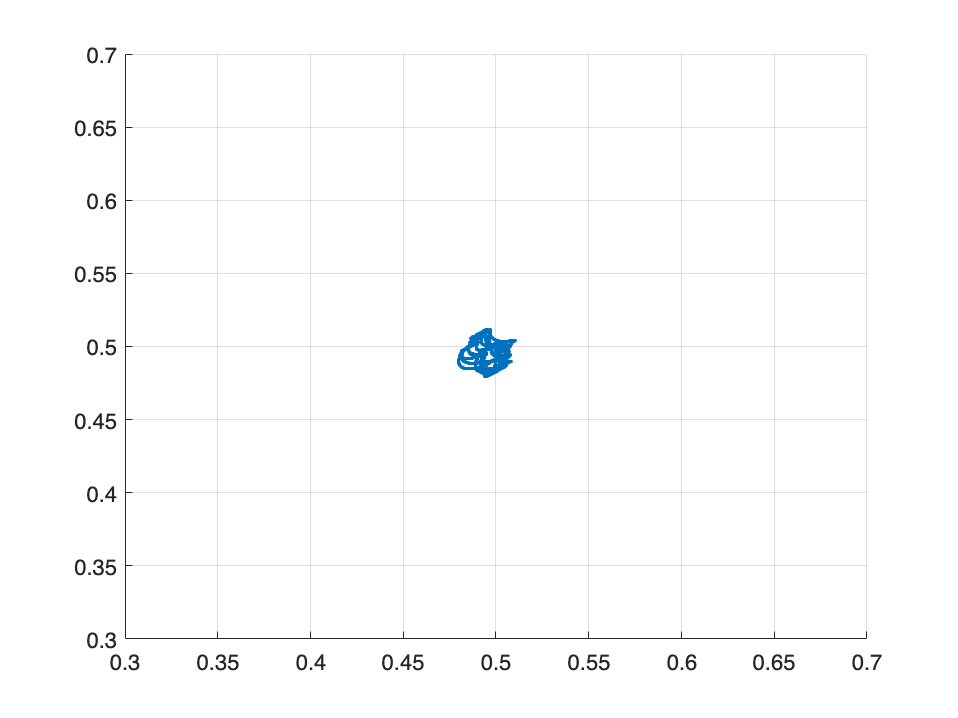


x_out = out.x_out';
y_out = out.y_out';
theta_out = out.theta_out';

scatter(x_out,y_out,1)
ylim([0.3 0.7])
xlim([0.3 0.7])
grid on

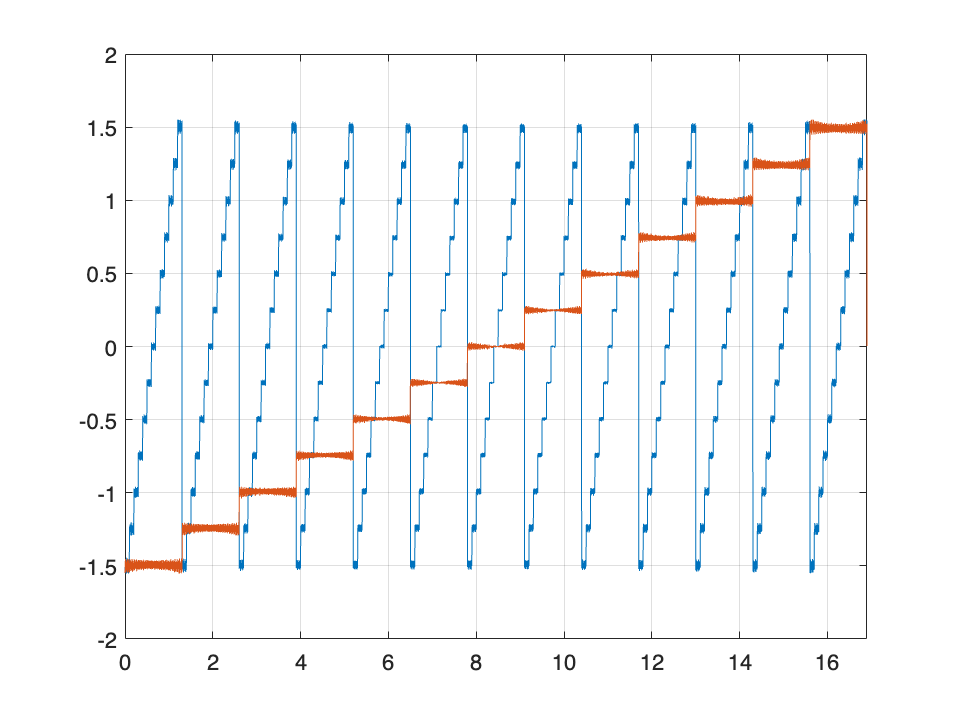

tt = linspace(0,stop_time,length(x_out));
plot(tt, x_out, tt, y_out)
ylim([-2 2])
xlim([0 stop_time])
grid on

mean(x_out(1,1:length(x_out)/length(x_var)))

ans = -1.4977

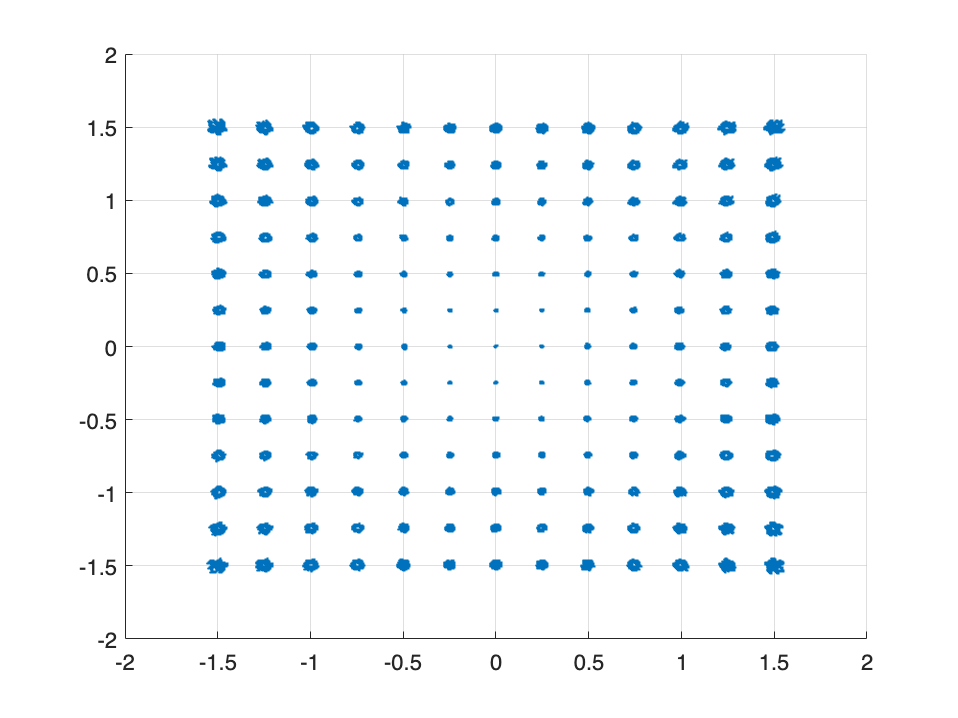

x_total_out = [x_total_out x_out];
y_total_out = [y_total_out y_out];
scatter(x_total_out, y_total_out,0.5)
ylim([-2 2])
xlim([-2 2])
grid on

save('xy_out_sensor_r48_degree5_kg4250_mesh_1_0.2_0.2_0.5.mat',"x_total_out","y_total_out","theta_out")